# Documentation

The data are taken from Želi et al. [1] which are openly available on Zenodo at [https://zenodo.org/record/3937500.](https://zenodo.org/record/3937500.) These data are four different simulations of the first and second-order flow characteristics in the stable atmospheric boundary layer. 

The script explore the data for two purposes:

- Check that a simple Matlab implementation of the Bulk Richardson Number gives realistic results

- Apply a sinple shallow Neural network to predict the profile of the standard deviation of the along-wind velocity component, knowing only the profiles of the two hroizontal mean velocity component and the profile of the standard deviation of the vertical velocity component.

[1] Želi, V., Brethouwer, G., Wallin, S.,  & Johansson, A. V. (2020). Modelling of stably stratified  atmospheric boundary layers with varying stratifications. *Boundary-Layer Meteorology*, *176*(2), 229-249.

## Loading the data

clearvars;close all;clc;

load('data.mat','z','H','U','V','Ri','theta','stdU','stdV','stdW','u_star');


Ri(Ri>0.5)=nan; % Richardson number above 0.5 are set as NaN
u_star(u_star<0.001) = nan; % Low friction velocity as set as NaN

[Nsamples,N]=size(z);


clf;close all;
figure
tiledlayout(1,2,"TileSpacing","tight")
nexttile
plot(H,z(1,:),'linewidth',1.2)
ylabel('z (m)')
xlabel('Mean wind speed (m/s)')
nexttile
plot(theta,z(1,:),'linewidth',1.2)
xlabel('\Theta (K)')

clf;close all;
figure
tiledlayout(1,3,"TileSpacing","tight")
nexttile
plot(stdW,z(1,:),'linewidth',1.2)
ylabel('z (m)')
xlabel('$\sigma_w$ (m/s)','interpreter','latex')
nexttile
plot(stdU,z(1,:),'linewidth',1.2)
xlabel('$\sigma_u$ (m/s)','interpreter','latex')
nexttile
plot(u_star,z(1,:),'linewidth',1.2)
xlabel('$u_*$ (m/s)','interpreter','latex')

## Estimate the Bulk Richardson number

Ri1 = zeros(Nsamples,N-1);
z1 = zeros(Nsamples,N-1);
for jj=1:Nsamples,
    for ii=1:N-1
        [Ri1(jj,ii)] = BulkRichardson(theta(jj,ii:ii+1),U(jj,ii:ii+1),V(jj,ii:ii+1),z(jj,ii:ii+1));
        z1(jj,ii)= mean(z(jj,ii:ii+1));
    end
end
Ri1(Ri1>0.5)=nan;
Ri1 = interp1(z1(1,:),Ri1',z(1,:))';

clf;close all;
figure
tiledlayout(1,Nsamples,"TileSpacing","tight")
for ii=1:Nsamples,
    nexttile
    
    plot(Ri(ii,:),z(1,:),'linewidth',1.2)
    title(['Case ' , num2str(ii)])
    hold on
    plot(Ri1(ii,:),z(1,:),'k--','linewidth',1.2)
    if ii==1,
        legend('Target','Estimated','location','best');
        ylabel('z (m)')
    end
    xlabel('Ri_b')
end

## Use a shallow ANN to estimate the profile of $\sigma_u$

We assume only a few number of heights are known for the along-wind velocity component

indSamples = [1 2 4] 

indSamples =      1     2     4


indMinZ = 10;
indMaxZ = 200

indMaxZ = 200

indZ = [indMinZ 100 indMaxZ];
% Train the ANN
dummyU = nan(size(stdU))

dummyU =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

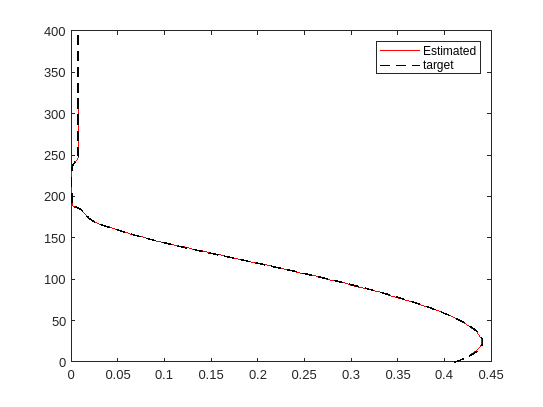

dummyU(:,indZ) = stdU(:,indZ); 


[net] = get_stdU(z(indSamples,[indMinZ:indMaxZ]),...
    stdW(indSamples,[indMinZ:indMaxZ]),...
    U(indSamples,[indMinZ:indMaxZ]),...
    V(indSamples,[indMinZ:indMaxZ]),...
    stdU(indSamples,[indMinZ:indMaxZ]));


% Check that the prediction is OK with sample no 3
indTarget =  [3];
clear x
x(1,:) = z(indTarget,[indMinZ:indMaxZ]);
x(2,:) = stdW(indTarget,[indMinZ:indMaxZ]);
x(3,:) = U(indTarget,[indMinZ:indMaxZ]);
x(4,:) = V(indTarget,[indMinZ:indMaxZ]);

% use the trained ANN
y = net(x);

clf;close all;
figure
plot(y,z(1,[indMinZ:indMaxZ]),'r','linewidth',1.2)
hold on
plot(stdU(indTarget,:),z(1,:),'k--','linewidth',1.2)
legend('Estimated','target')